fprintf('please Select an image');

please Select an image

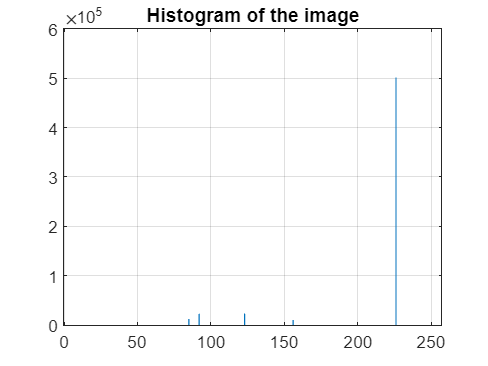

y=uigetfile('*.*');
i=imread(y);
d=rgb2gray(i);
[r,c]=size(d);
%Here the histogram is diplayed
funchist=imhist(d);
subplot(1,1,1);bar(funchist);title('Histogram of the image');grid on;

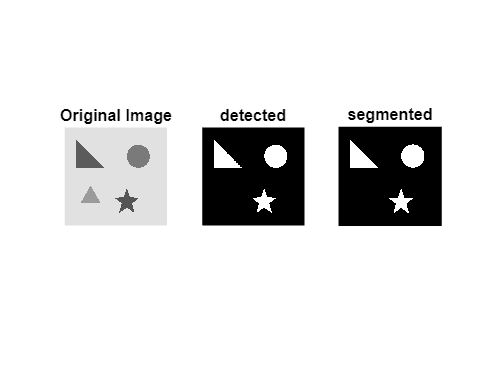

%Here the threshold values are set.
s=zeros(r,c);
for R =1:r
   for C=1:c
      if d(R,C)==91 || d(R,C)==84 ||d(R,C)==122
          s(R,C)=1;
      else
          s(R,C)=0;
      end

   end
end

subplot(1,3,1);imshow(d);title('Original Image');
subplot(1,3,2);imshow(s);title('detected');
subplot(1,3,3);imshow(double(d).*s);title('segmented');